# **Lab 4**

## **Experiment 1-4**

**Part 1**

step 1

b_tx = bit_gen(10,4)

b_tx =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


b_gray = gray_code(2)

b_gray =      0     0
     0     1
     1     1
     1     0


step 2

pkt_size = 10;
sym_idx = zeros(pkt_size,1);
for i=1:length(b_tx)
    temp = b_tx(i,:);
    for j=0:length(b_gray)-1
        if b_gray(j+1,:) == temp
            sym_idx(i) = j;
            break;
        end
    end
end
sym_idx

sym_idx =      0
     2
     0
     1
     0
     1
     0
     1
     0
     3


Step 3

mod_values = constellation(4,'pam');
mod_sym = zeros(pkt_size,1);
for i=1:length(sym_idx)
    mod_sym(i) = mod_values(sym_idx(i)+1);   
end
mod_sym

mod_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


 Part 3

tx_smpl =pulse_modulation(sym_idx, 'pam', 4, 1, 8, 'triangular' , 'kron', 0)

tx_smpl =          0
   -0.2023
   -0.4045
   -0.6068
   -0.8090
   -0.6068
   -0.4045
   -0.2023
         0
    0.0674


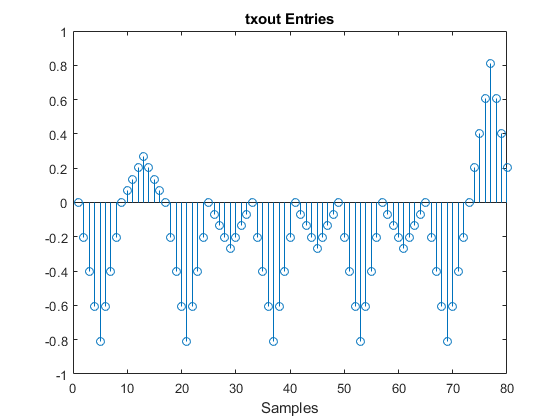

t = 1:80;
stem(t,tx_smpl)
title('txout Entries')
xlabel('Samples')

**Experiment 4-2)**

part 1)

[p, t] = pulse_shape('triangular', 1, 8);
%matched filter
rx_sym = corr_match(tx_smpl, p, 8, 1)

rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


%correlation
rx_sym = corr_match(tx_smpl, p, 8, 2)

rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


part 2)

[cons, Es_avg] = constellation(4, 'pam');
[det_sym] = min_dist_detector(rx_sym, cons);
det_sym = det_sym - 1

det_sym =      0
     2
     0
     1
     0
     1
     0
     1
     0
     3


part 3)

%MatchedFilter
[det_sym_idx, rx_sym] = pulse_demodulation(tx_smpl, 'pam', 4, 1, 8, 'triangular' , 1, 0)

det_sym_idx =      0
     2
     0
     1
     0
     1
     0
     1
     0
     3


rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


%Correlation
[det_sym_idx2, rx_sym2] = pulse_demodulation(tx_smpl, 'pam', 4, 1, 8, 'triangular' , 2, 0)

det_sym_idx2 =      0
     2
     0
     1
     0
     1
     0
     1
     0
     3


rx_sym2 =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


part 4)

k=2;
det_bit = zeros(pkt_size,k);
for i=1:10
    index = det_sym_idx(i);
    det_bit(i,:) = b_gray(index+1,:);
end
det_bit

det_bit =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0
